# JoyStick Demo - Gator Summer 2022

### REV A

Joystick Demo to drive the Gator via a usb connected joystick to the main system

%%% Path Declaration
addpath(...
    "ACT\",...
    "GPSCOORDS\",...
    "SENSE\",...
    "SETUP\",...
    "SHUTDOWN\",...
    "THINK\")
disp("FOLDER PATHS ADDED")

FOLDER PATHS ADDED


%%$ Variable Decleration
controlFlag = 1;                                   % Start Control counter
% sampleTime = 0.0001;                                  % Sample time [s]
% t = 0:sampleTime:100;                              % Time array
% r = rateControl(1/sampleTime);                     % reset control loop  rate
% reset(r);                                          % reset loop time to zero
wayStep=1;

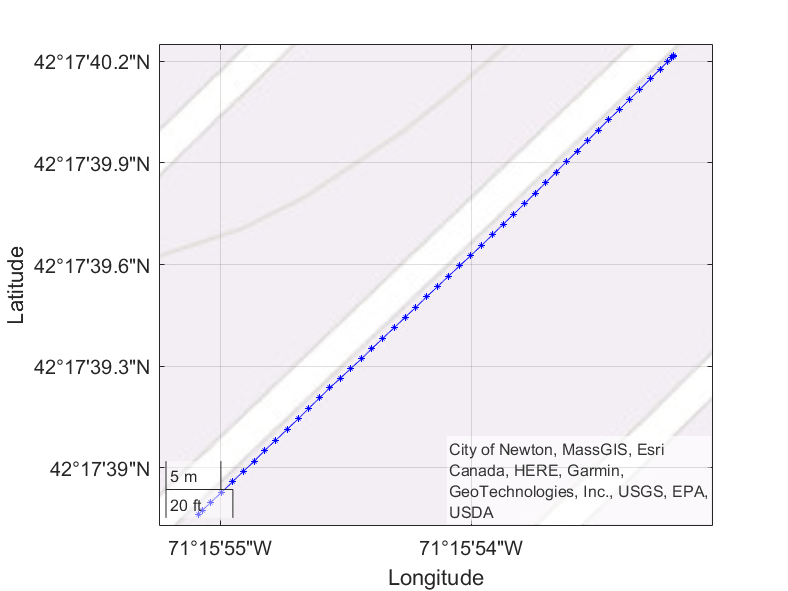

%%% SETUP 
%Setup GPS
hold off

ggaData = 144×1 struct array with fields:
    TalkerID
    MessageID
    FixStatus
    Latitude
    Longitude
    GroundSpeed
    TrueCourseAngle
    UTCDateTime
    MagneticVariation
    ModeIndicator
    NavigationStatus
    Status


[lat1,lon1,UTCDateTime1]=PlotGPSlog("C:\Users\Skull\Documents\GatorTemp\RTK_GPS\GPS_Right_Data_Parkinglot.ubx");

ggaData = 144×1 struct array with fields:
    TalkerID
    MessageID
    FixStatus
    Latitude
    Longitude
    GroundSpeed
    TrueCourseAngle
    UTCDateTime
    MagneticVariation
    ModeIndicator
    NavigationStatus
    Status


[lat2,lon2,UTCDateTime2]=PlotGPSlog("C:\Users\Skull\Documents\GatorTemp\RTK_GPS\GPS_Right_Data_Parkinglot.ubx");

if  UTCDateTime1(1,1)< UTCDateTime2(1,1)
      for i=1:size(lat1,2)
        if  UTCDateTime1(1,i)==UTCDateTime2(1,1)
            start=i
            disp("Found")
            break
        end
      end
    sizearray=size(lat2,2);
    lat1new=lat1(1,start:start+sizearray-1);
    lon1new=lon1(1,start:start+sizearray-1);
    lat2new=lat2(1,1:size(lat1new,2));
    lon2new=lon2(1,1:size(lat1new,2));

else
       for i=1:size(lat2,2)
        if  UTCDateTime1(1,i)==UTCDateTime2(1,1)
            start=i
            disp("Found")
            break
        end
      end
    sizearray=size(lat1,2);
    lat2new=lat2(1,start:start+sizearray-1);
    lon2new=lon2(1,start:start+sizearray-1);
    lat1new=lat1(1,1:size(lat2new,2));
    lon1new=lon1(1,1:size(lat2new,2));
end

start = 1

Found


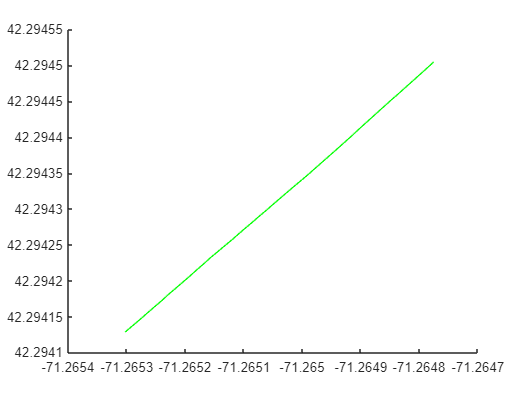


clf
middlelat=mean([lat1new; lat2new]);
middlelon=mean([lon1new; lon2new]);
waypoints=[middlelat(1:4:end);middlelon(1:4:end)];
figure(2)
start=1;
section=size(middlelat,2);
hold on
plot(middlelon(start:section),middlelat(start:section),'-b');
 plot(lon1new(start:section),lat1new(start:section),'-y');
 plot(lon2new(start:section),lat2new(start:section),'-g');
hold off

objects1 = setupGPSDemo('COM7')

Warning! RoboClaw must be OFF before runnin this code
Lights ON = CONNECTED
Please Power up RoboClaw Now
MEGA CONNNECTED
SUCCESS: Sent termination signal to the process "cmd.exe" with PID 4992. 
SUCCESS: Sent termination signal to the process "cmd.exe" with PID 9760. 
SUCCESS: Sent termination signal to the process "cmd.exe" with PID 7460. 
^C

ans = -1.0737e+09

Configure GPS RTK
1. Close Command lines
2. Open U Center
3. Connect to GPS sensor with 9600 Buad (Check Device Manager for COM #)
4. Setup RTK, go to NTRIP Client Settings
5. Credientals 1:IP address: 66.128.64.251Port: 31000Username: cbabePassword: deere1#
6. Credientals 2
7. Click Mount Point details and select RTCM3_MAMI (MAMI is the closest RTK Station)
8. Click ok
9. RTK data should be sending to the GPS (On the GPS-RTK-SMA ZED-F9P the Green RTK light should blink and eventually turn off after the GPS gets an RTK fix)
10. Create a new document named: C:\Users\Skull\Documents\GatorTemp\RTK_GPS\GPS_1_Data.ubx
11. Create a new document named: C:\Users\Skull\Documents\GatorTemp\RTK_GPS\GPS_2_Data.ubx
More information is avalible at: https://macors.massdot.state.ma.us/SBC/Account/Index?returnUrl=%2FSBC
Username: cbabe
Password: deere850
Press any key to continue
GPS CONNNECTED


objects1 = struct with fields:
    Mega: [1×1 struct]


%%% MAIN
wayStep=1;
senseobjects=sense(objects1);
[motorControls, wayStep]=thinkPathB2C(senseobjects, waypoints, wayStep);
motorControls.throttle=0;
actGPS(objects1.Mega, motorControls);
disp("Turn on Linear Actuators") 

Turn on Linear Actuators


pause
while (controlFlag > 0)           % loop for number of elements in t
    senseobjects=sense(objects1);

    [motorControls, wayStep]=thinkPathB2C(senseobjects, waypoints, wayStep);
    actGPS(objects1.Mega, motorControls);
    controlFlag = controlFlag+1;         % increment loops
    if wayStep>size(waypoints,2)
        disp("Hi")
        motorControls.throttle=-1;
        actGPS(objects.Mega, motorControls)
        break
    end

end 

wayStep

wayStep =      8


%%% SHUTDOWN
clear